# Método Runge Kutta 4th orden - Actividad 2

#### Curso: Modelación computacional de sistemas electromagnéticos (Gpo 313)

#### Docente: Mara Félix

#### Elaborado por: 

#### Liliana Solórzano Pérez A01641392 

#### Nolberto Castro Sánchez A01641501

Problema 1

a) Solución analítica: $y\left(t\right)=2e^{-10t}$, voltaje del capacitor: $y\left(0\right)=2V$

%Limpiamos las variables
clear;
clc; clear allvars;

%Condiciones iniciales
h = 0.1;
x=0:h:4;
y = zeros(1,length(x));
y(1)=2;
y2(1)=15;

%Funciones del problema 1
%Definimos nuestra función anónima. Es una ecuación diferencial ordinaria.
%dy/dx = f(x,y)
funcion=@(x,y)(-y/0.1);
%solución analítica
sol_analitica = @(x) 2*exp(-10*x);

%-------------------------Funciones del problema---------------------------
%Función del problema 2
problema2_funcion = @(x,y)(20+7*sin(2*x)-y)/10;
%Solución analítica problema 2
sol_analitica_2 = @(x) 20+7.*((1./401).*sin(2.*x)-(20/401).*cos(2.*x))-(1865./(401.*exp(x./10)));

%For de solución analítica para problema 1 y 2
sol_ana = zeros(1,length(x));
sol_ana2 = zeros(1,length(x));
for i = 1:length(x)
sol_ana(i) = sol_analitica(x(i));
sol_ana2(i)=sol_analitica_2(x(i));
end

%------------------Método Runge Kutta 4-------------------------



Grafico de los resultados del método Runge Kutta 4 y su solución analítica del problema 1 y 2

%----------------Gráfico del problema 1-----------------
figure()
hold on
title('Método Runge Kutta 4, aproximación RC')
%graficamos la solución analítica
plot(x, sol_ana, '-or');
%Método de Runge Kutta RC
y = rungeKutta(x,y,h,funcion,sol_analitica);

error_rungeKutta = 0

error_rungeKutta = 1.9356

error_rungeKutta = 3.9086

error_rungeKutta = 5.9198

error_rungeKutta = 7.9700

error_rungeKutta = 10.0598

error_rungeKutta = 12.1901

error_rungeKutta = 14.3616

error_rungeKutta = 16.5752

error_rungeKutta = 18.8315

error_rungeKutta = 21.1316

error_rungeKutta = 23.4762

error_rungeKutta = 25.8662

error_rungeKutta = 28.3024

error_rungeKutta = 30.7858

error_rungeKutta = 33.3172

error_rungeKutta = 35.8977

error_rungeKutta = 38.5281

error_rungeKutta = 41.2094

error_rungeKutta = 43.9426

error_rungeKutta = 46.7287

error_rungeKutta = 49.5687

error_rungeKutta = 52.4637

error_rungeKutta = 55.4148

error_rungeKutta = 58.4229

error_rungeKutta = 61.4893

error_rungeKutta = 64.6150

error_rungeKutta = 67.8013

error_rungeKutta = 71.0492

error_rungeKutta = 74.3600

error_rungeKutta = 77.7348

error_rungeKutta = 81.1750

error_rungeKutta = 84.6818

error_rungeKutta = 88.2564

error_rungeKutta = 91.9002

error_rungeKutta = 95.6146

error_rungeKutta = 99.4008

error_rungeKutta = 103.2604

error_rungeKutta = 107.1946

error_rungeKutta = 111.2050

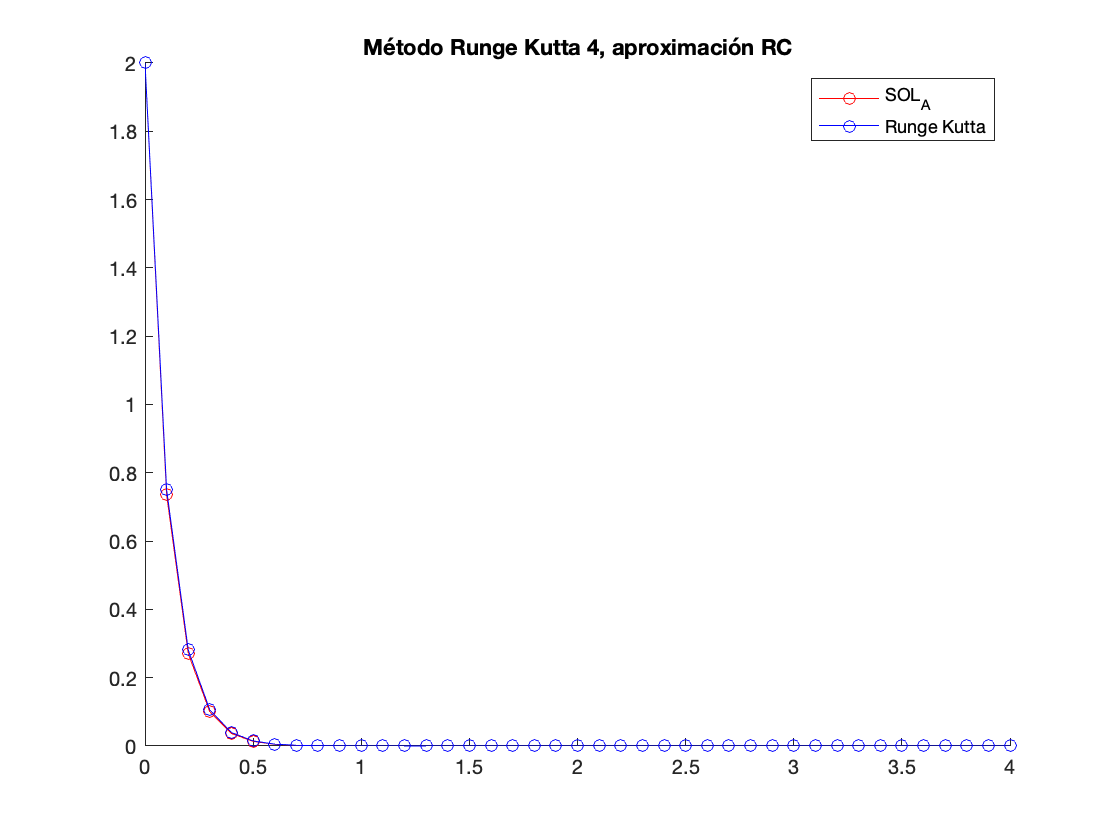

plot(x,y,'-ob');
legend('SOL_A','Runge Kutta')
hold off


%--------------------Gráfico ejercicio 2---------------------
figure()
hold on
title('Método Runge Kutta 4, ejercicio 2')
%graficamos la solución analítica
plot(x, sol_ana2, '- *r');
%Método de Runge Kutta
y = rungeKutta_ejercicio_2(x,y2,h,problema2_funcion,sol_analitica_2);

error_rungeKutta2 = 0

error_rungeKutta2 = 2.5102e-08

error_rungeKutta2 = 1.5580e-09

error_rungeKutta2 = 7.7650e-08

error_rungeKutta2 = 1.9871e-07

error_rungeKutta2 = 3.5843e-07

error_rungeKutta2 = 5.4900e-07

error_rungeKutta2 = 7.6156e-07

error_rungeKutta2 = 9.8664e-07

error_rungeKutta2 = 1.2145e-06

error_rungeKutta2 = 1.4358e-06

error_rungeKutta2 = 1.6414e-06

error_rungeKutta2 = 1.8233e-06

error_rungeKutta2 = 1.9743e-06

error_rungeKutta2 = 2.0888e-06

error_rungeKutta2 = 2.1622e-06

error_rungeKutta2 = 2.1917e-06

error_rungeKutta2 = 2.1758e-06

error_rungeKutta2 = 2.1147e-06

error_rungeKutta2 = 2.0102e-06

error_rungeKutta2 = 1.8657e-06

error_rungeKutta2 = 1.6859e-06

error_rungeKutta2 = 1.4773e-06

error_rungeKutta2 = 1.2471e-06

error_rungeKutta2 = 1.0040e-06

error_rungeKutta2 = 7.5702e-07

error_rungeKutta2 = 5.1575e-07

error_rungeKutta2 = 2.8966e-07

error_rungeKutta2 = 8.7765e-08

error_rungeKutta2 = 8.1841e-08

error_rungeKutta2 = 2.1240e-07

error_rungeKutta2 = 2.9883e-07

error_rungeKutta2 = 3.3802e-07

error_rungeKutta2 = 3.2898e-07

error_rungeKutta2 = 2.7285e-07

error_rungeKutta2 = 1.7283e-07

error_rungeKutta2 = 3.4005e-08

error_rungeKutta2 = 1.3702e-07

error_rungeKutta2 = 3.3243e-07

error_rungeKutta2 = 5.4362e-07

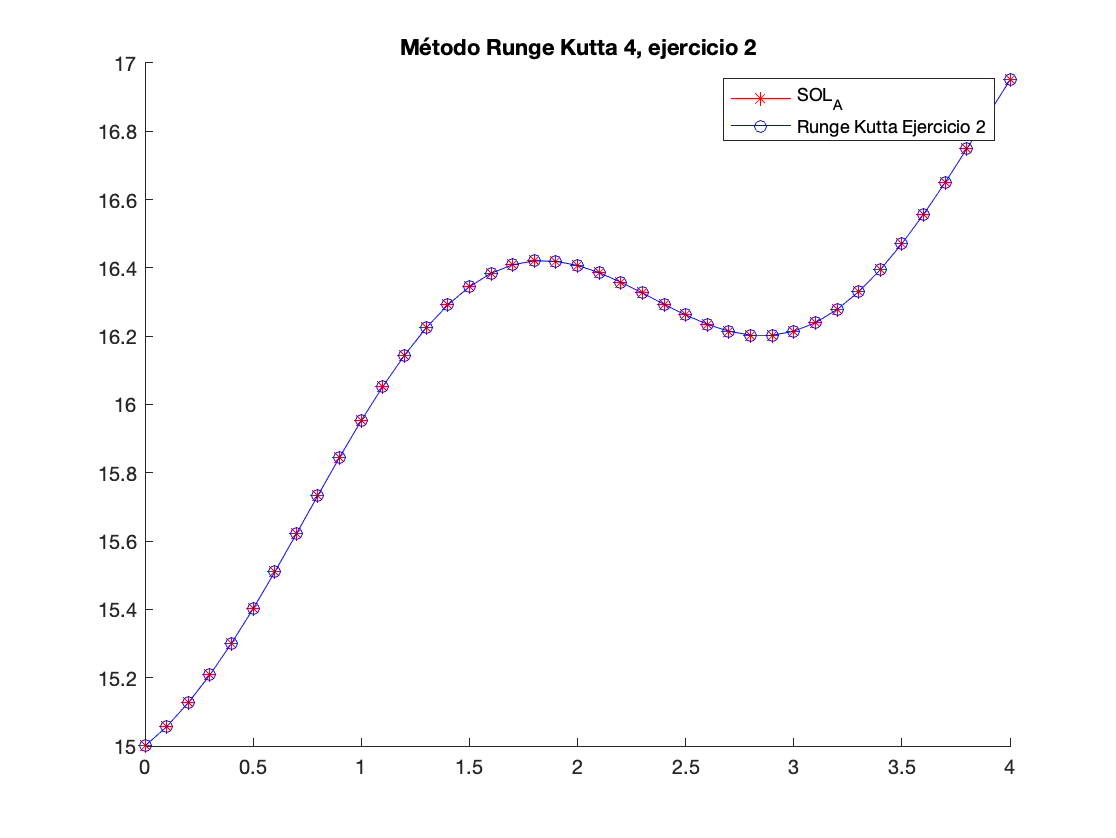

plot(x,y,'-ob');
legend('SOL_A','Runge Kutta Ejercicio 2')
hold off

function y = rungeKutta(x,y,h,f,fsol_analitica)
    ysiguiente = @(y,k_1,k_2,k_3,k_4,h) y+ (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;
for i=1:(length(x)-1)                             
    k_1 = f(x(i),y(i));
    k_2 = f(x(i)+0.5*h,y(i)+0.5*h*k_1);
    k_3 = f((x(i)+0.5*h),(y(i)+0.5*h*k_2));
    k_4 = f((x(i)+h),(y(i)+k_3*h));
    y(i+1)= ysiguiente(y(i),k_1,k_2,k_3,k_4,h);
    error_rungeKutta = abs(fsol_analitica(x(i))-y(i))/fsol_analitica(x(i))*100

    %y(i+1) = y(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;  % ecuación principal
end
end

function y = rungeKutta_ejercicio_2(x,y,h,fproblema2_funcion,fsol_analitica_2)
    ysiguiente = @(y,k_1,k_2,k_3,k_4,h) y+ (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;
for i=1:(length(x)-1)                             
    k_1 = fproblema2_funcion(x(i),y(i));
    k_2 = fproblema2_funcion(x(i)+0.5*h,y(i)+0.5*h*k_1);
    k_3 = fproblema2_funcion((x(i)+0.5*h),(y(i)+0.5*h*k_2));
    k_4 = fproblema2_funcion((x(i)+h),(y(i)+k_3*h));
    y(i+1)= ysiguiente(y(i),k_1,k_2,k_3,k_4,h);
    error_rungeKutta2 = abs(fsol_analitica_2(x(i))-y(i))/fsol_analitica_2(x(i))*100

    %y(i+1) = y(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;  % ecuación principal
end
end









